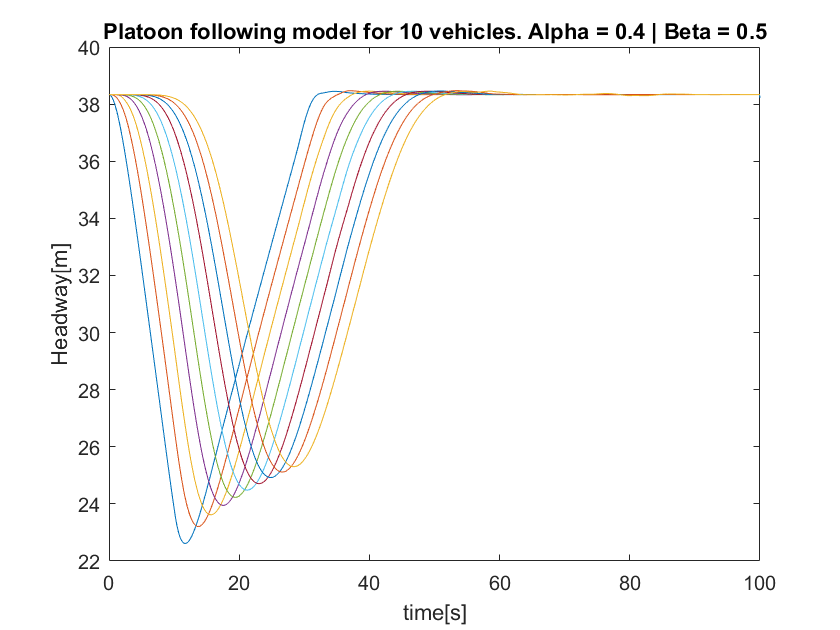

%HW2_Q2 Connected

clear all

follow_num = 10; %Number of followers
vmax = 30;
kappa = 0.6;
hstop = 5;
hgo = hstop + vmax/kappa;
tstart = 0;
tend = 100;
tdelta = 0.1;
vstar = 20;
hstar = vstar/kappa + hstop;
alpha = 0.4;
beta = 0.5;
a = 1;
b = 0.5;

%initial conditions
h0 = hstar*ones(follow_num,1); %Here assuming that all vehicles start with vstar velocity and with hstar distacnce between them
v0 = vstar*ones(follow_num,1);
y0 = [h0 ; v0];
y0 = y0';

tspan = tstart:tdelta:tend;
[t,y] = ode45(@(t,y)odefunc(t,y,kappa,alpha,beta,...
        hstop,hgo,vmax,vstar,a,b,follow_num),tspan,y0);
  
headways = y(:,1:follow_num);
velocities = y(:,follow_num+1:2*follow_num);

figure(1);
plot(t,headways);
xlabel('time[s]');
ylabel('Headway[m]');
title("Platoon following model for "+follow_num+...
    " vehicles. Alpha = "+alpha+" | Beta = "+beta);

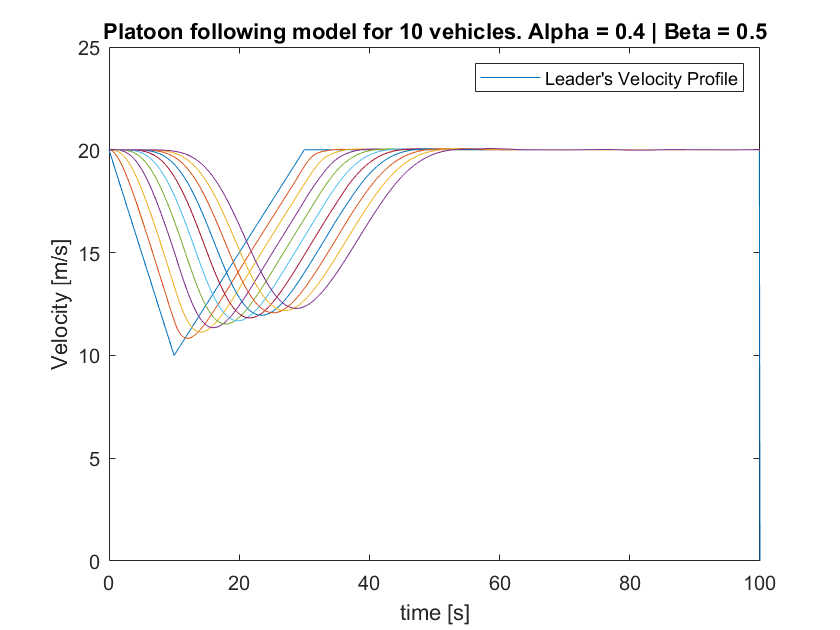


figure(2);
plot(t,vlead_func(t,vstar,a,b)); %Can change the leader velocity to any required...
%profile from the function below 
hold on;
plot(t,velocities);
xlabel('time [s]');
ylabel('Velocity [m/s]');
title("Platoon following model for "+follow_num+...
    " vehicles. Alpha = "+alpha+" | Beta = "+beta);
legend('Leader''s Velocity Profile');

function dydt = odefunc(t,y,kappa,alpha,beta,hstop,hgo,vmax,vstar,a,b,follow_num)
%state [h1;h2;h3;.....;hfollow_num ; v1;v2;v3....;vfollow_num]
h = y(1:follow_num);
vF = y(follow_num+1:2*follow_num);  %velocity of all followers
vL = [vlead_func(t,vstar,a,b);
      vF(1:follow_num-1)] ;         %velocity of all the leaders,
                                    % every vehicle except the last 
                                    % one will be someone's leader.

%range policy
Vh = 0 + ((hstop<h)&(h<hgo)).*(kappa.*(h-hstop)) + (h>=hgo).*(vmax);

dydt = [(vL-vF);(alpha.*(Vh-vF)+beta.*(vL-vF))];

% dydt(1) = v_lead - y(follow_num + 1);
% 
% dydt(follow_num+1) = alpha*(0 +...
%                      ((hstop<y(1))&(y(1)<hgo))*(kappa*(y(1)-hstop))+(y(1)>=hgo)*(vmax)...
%                      - y(follow_num + 1))...
%                      + beta*(v_lead - y(follow_num + 1));  
%    
% i = 2;
% j = follow_num+2;
% while (((2<=i)&&(i<=follow_num)) && ((follow_num + 2<=j)&&(j<=2*follow_num)))
%     dydt(i) = y(i - 1) - y(i); 
%     dydt(j) = alpha*(0 +...
%               ((hstop<y(i))&(y(i)<hgo))*(kappa*(y(i)-hstop))+(y(i)>=hgo)*(vmax)...
%               - y(j))...
%               + beta*(y(j-1) - y(j));
%     i = i + 1;
%     j = j + 1;
% end
%     
% dydt = dydt';
end

function vl = vlead_func(t,vstar,a,b)
t1 = 10;
t2 = 30;
t3 = 100;
    vl = ((0<=t)&(t<t1)).*(vstar - a.*t) +...
         ((t1<=t)&(t<t2)).*(vstar + b.*(t-t2)) +...
         ((t2<=t)&(t<t3)).*vstar;      
%   vl =15+ 6*cos(t);
end

